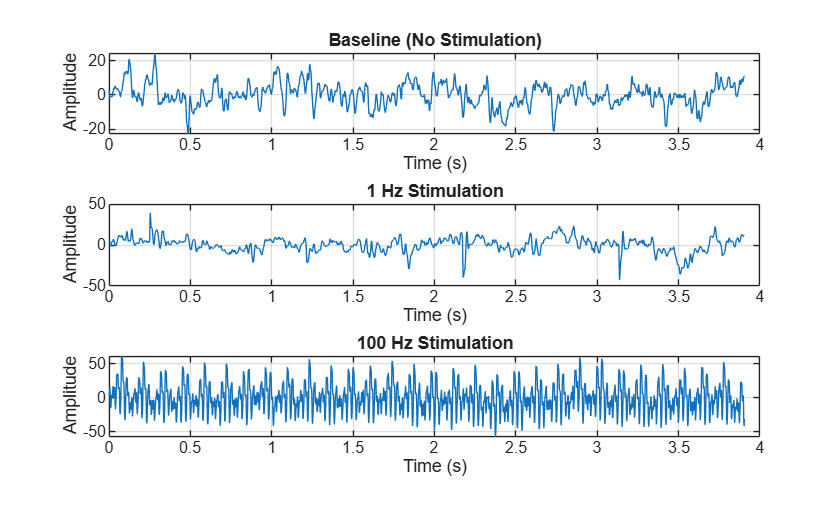

% Lab Task 3: Harmonic estimation for brain signals

clear; clc; close all;
load('data/eeg_stimul_data.mat'); 
fs = 512; 

% Create time vectors for plotting the raw signals
t_baseline = (0:length(x_baseline)-1) / fs;
t_1Hz      = (0:length(x_1Hz_stimul)-1) / fs;
t_100Hz    = (0:length(x_100Hz_stimul)-1) / fs;

% Part 0: Plotting Raw Signals
figure('Name', 'Raw EEG Signals');

subplot(3,1,1); 
plot(t_baseline, x_baseline); 
title('Baseline (No Stimulation)'); 
xlabel('Time (s)'); ylabel('Amplitude'); grid on;

subplot(3,1,2); 
plot(t_1Hz, x_1Hz_stimul); 
title('1 Hz Stimulation'); 
xlabel('Time (s)'); ylabel('Amplitude'); grid on;

subplot(3,1,3); 
plot(t_100Hz, x_100Hz_stimul); 
title('100 Hz Stimulation'); 
xlabel('Time (s)'); ylabel('Amplitude'); grid on;

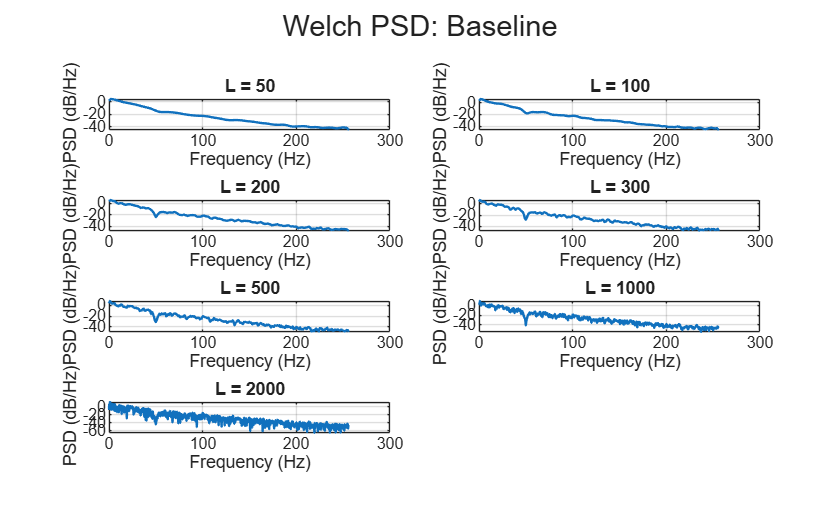

%% Part 1: Welch Method
windows = [50, 100, 200, 300, 500, 1000, 2000];

% 1. Baseline - Welch
figure('Name', 'Welch Method Baseline');
for i = 1:length(windows)
    L = windows(i);
    [pxx, f_welch] = pwelch(x_baseline, L, round(L/2), [], fs);
    
    subplot(4, 2, i);
    plot(f_welch, 10*log10(pxx), 'LineWidth', 1.2); 
    title(['L = ', num2str(L)]); 
    xlabel('Frequency (Hz)'); ylabel('PSD (dB/Hz)'); grid on;
end
sgtitle('Welch PSD: Baseline'); 

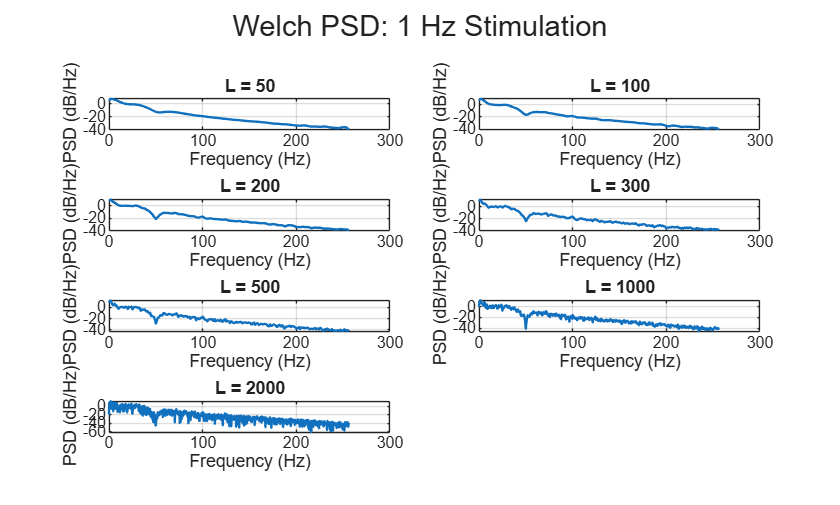


% 2. 1 Hz Stimulation  Welch
figure('Name', 'Welch Method  1 Hz');
for i = 1:length(windows)
    L = windows(i);
    [pxx, f_welch] = pwelch(x_1Hz_stimul, L, round(L/2), [], fs);
    
    subplot(4, 2, i);
    plot(f_welch, 10*log10(pxx), 'LineWidth', 1.2); 
    title(['L = ', num2str(L)]); 
    xlabel('Frequency (Hz)'); ylabel('PSD (dB/Hz)'); grid on;
end
sgtitle('Welch PSD: 1 Hz Stimulation');

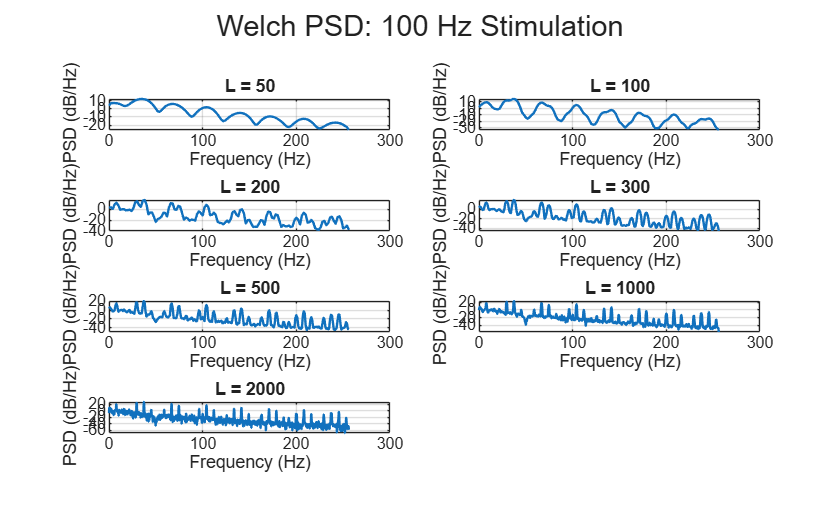


% 3. 100 Hz Stimulation  Welch
figure('Name', 'Welch Method - 100 Hz');
for i = 1:length(windows)
    L = windows(i);
    [pxx, f_welch] = pwelch(x_100Hz_stimul, L, round(L/2), [], fs);
    
    subplot(4, 2, i);
    plot(f_welch, 10*log10(pxx), 'LineWidth', 1.2); 
    title(['L = ', num2str(L)]); 
    xlabel('Frequency (Hz)'); ylabel('PSD (dB/Hz)'); grid on;
end
sgtitle('Welch PSD: 100 Hz Stimulation');

%% Part 2: AR-Method
P_ar = [1, 2, 10, 15, 20, 30, 50, 60, 70, 100];

% 1. Baseline - AR
figure('Name','AR Method - Baseline');
n = length(P_ar);
cols = ceil(sqrt(n));
rows = ceil(n/cols);
t = tiledlayout(rows, cols, TileSpacing="compact");


for i = 1:n
    P = P_ar(i);
    [Phi, f_grid] = my_AR_spectrum(x_baseline, P, fs);
    nexttile;
    plot(f_grid, 10*log10(Phi), 'LineWidth', 1.2);
    title(['P = ', num2str(P)]);
    xlabel('Frequency (Hz)'); ylabel('Power (dB)'); grid on;
end

my_AR_spectrum is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\Claudia\Documents\Github\biosignal-processing-lab1\lab2\matlab

Change the MATLAB current folder or add its folder to the MATLAB path.

sgtitle('AR Spectrum: Baseline');

% 2. 1 Hz Stimulation - AR
figure('Name', 'AR Method - 1 Hz');
n = length(P_ar);
cols = ceil(sqrt(n));
rows = ceil(n/cols);
t = tiledlayout(rows, cols, TileSpacing="compact");

for i = 1:n
    P = P_ar(i);
    [Phi, f_grid] = my_AR_spectrum(x_1Hz_stimul, P, fs);
    nexttile; 
    plot(f_grid, 10*log10(Phi), 'LineWidth', 1.2); 
    title(['P = ', num2str(P)]); 
    xlabel('Frequency (Hz)'); ylabel('Power (dB)'); grid on;
end
sgtitle('AR Spectrum: 1 Hz Stimulation');

% 3. 100 Hz Stimulation - AR
figure('Name', 'AR Method - 100 Hz');
n = length(P_ar);
cols = ceil(sqrt(n));
rows = ceil(n/cols);
t = tiledlayout(rows, cols, TileSpacing="compact");

for i = 1:n
    P = P_ar(i);
    [Phi, f_grid] = my_AR_spectrum(x_100Hz_stimul, P, fs);
    nexttile; 
    plot(f_grid, 10*log10(Phi), 'LineWidth', 1.2); 
    title(['P = ', num2str(P)]); 
    xlabel('Frequency (Hz)'); ylabel('Power (dB)'); grid on;
end
sgtitle('AR Spectrum: 100 Hz Stimulation');


%% AR Pole Visualization - 100 Hz Stimulation

theta = linspace(0, 2*pi, 500);

figure('Name', 'AR Poles - 100 Hz Stimulation');

n = length(P_ar);
cols = ceil(sqrt(n));
rows = ceil(n/cols);
tiledlayout(rows, cols, TileSpacing="compact");

for i = 1:n
    P = P_ar(i);

    % Estimate AR coefficients
    a = aryule(x_100Hz_stimul, P);

    % Obtain poles of the AR model
    poles = roots(a);

    nexttile;

    % Plot unit circle
    plot(cos(theta), sin(theta), 'k--');
    hold on;

    % Plot poles
    plot(real(poles), imag(poles), 'x', ...
        'MarkerSize', 7, 'LineWidth', 1.5);

    % Plot real and imaginary axes
    xline(0, ':');
    yline(0, ':');

    axis equal;
    xlim([-1.1 1.1]);
    ylim([-1.1 1.1]);
    grid on;

    title(['P = ', num2str(P)]);
    xlabel('Real Part');
    ylabel('Imaginary Part');
end

sgtitle('AR Poles: 100 Hz Stimulation');

% Part 3: Pisarenko and line spectrum estimation

% 1 and 2. Try different numbers of spectral lines (P) for 100 Hz stimulation
P_pisarenko = [2, 5, 10, 20]; 
figure('Name', 'Pisarenko Method Comparison - 100 Hz');

for i = 1:length(P_pisarenko)
    P = P_pisarenko(i);
    
    [f_pis, Phi_pis] = my_pisarenko(x_100Hz_stimul, P, fs);
    
    subplot(length(P_pisarenko), 1, i);
    stem(f_pis, Phi_pis, 'filled'); 
    title(['100 Hz Stimul, Pisarenko P = ', num2str(P)]);
    xlabel('Frequency (Hz)'); ylabel('Amplitude'); grid on;
end

% 3. Extract the 5 most significant components for x_100Hz_stimul using P=10
P_target = 10;
[f_100Hz, Phi_100Hz] = my_pisarenko(x_100Hz_stimul, P_target, fs);

[sorted_Phi, sort_idx] = sort(Phi_100Hz, 'descend');
sorted_f = f_100Hz(sort_idx);

disp('--- Top 5 components for x_100Hz_stimul (P = 10) ---');
for i = 1:min(5, length(sorted_Phi))
    fprintf('Component %d: Frequency = %6.2f Hz, Amplitude = %.4f\n', ...
             i, sorted_f(i), sorted_Phi(i));
end

% 4. Pisarenko method with P=10 for baseline and 1 Hz
[f_base, Phi_base] = my_pisarenko(x_baseline, P_target, fs);
[f_1Hz, Phi_1Hz]   = my_pisarenko(x_1Hz_stimul, P_target, fs);

figure('Name', 'Pisarenko (P=10) - Baseline vs 1Hz');
subplot(2,1,1);
stem(f_base, Phi_base, 'filled');
title('Pisarenko (P=10): Baseline'); xlabel('Frequency (Hz)'); ylabel('Amplitude'); grid on;

subplot(2,1,2);
stem(f_1Hz, Phi_1Hz, 'filled');
title('Pisarenko (P=10): 1 Hz Stimulation'); xlabel('Frequency (Hz)'); ylabel('Amplitude'); grid on;

[sorted_Phi_base, sort_idx_base] = sort(Phi_base, 'descend');
sorted_f_base = f_base(sort_idx_base);
disp(' ');
disp('--- Dominant components for x_baseline (P = 10) ---');
for i = 1:min(3, length(sorted_Phi_base))
    fprintf('Component %d: Frequency = %6.2f Hz, Amplitude = %.4f\n', ...
             i, sorted_f_base(i), sorted_Phi_base(i));
end

[sorted_Phi_1Hz, sort_idx_1Hz] = sort(Phi_1Hz, 'descend');
sorted_f_1Hz = f_1Hz(sort_idx_1Hz);
disp(' ');
disp('--- Dominant components for x_1Hz_stimul (P = 10) ---');
for i = 1:min(3, length(sorted_Phi_1Hz))
    fprintf('Component %d: Frequency = %6.2f Hz, Amplitude = %.4f\n', ...
             i, sorted_f_1Hz(i), sorted_Phi_1Hz(i));
end